# Sensitivity analysis

Let us analyze what parameter affects the output the most.

Copyright (C) 2022 Miodrag Bolic

  This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter4/ChargeAmplifierUncertainty'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Introduction

This example provides introduction to the charge amplifier circuit connected to the model of the piezoelectric transducer. This circuit is based on Analog Devices application note: [12-Bit, 1 MSPS, Single-Supply, Two-Chip Data Acquisition System for Piezoelectric Sensors](https://www.analog.com/media/en/reference-design-documentation/reference-designs/CN0350.pdf). 

## Running simulation with fixed parameters

% Running simulation
model_name='ChargeAmpl_sens';
plotting=1;
start_time=1000;
end_time=1500;
open_system(model_name)
simOut = sim(model_name, 'CaptureErrors', 'on');


% Setting parameters
SETTING_PARAM=0;
if SETTING_PARAM
    blockNames = find_system(model_name, 'Type' , 'Block' );
    for k = 1 : length( blockNames )
        set_param( blockNames{k} , 'ShowName' , 'on' );
    end;
    %set_param('ppg2/GND1' , 'ShowName' , 'off' );
end

Plotting results:

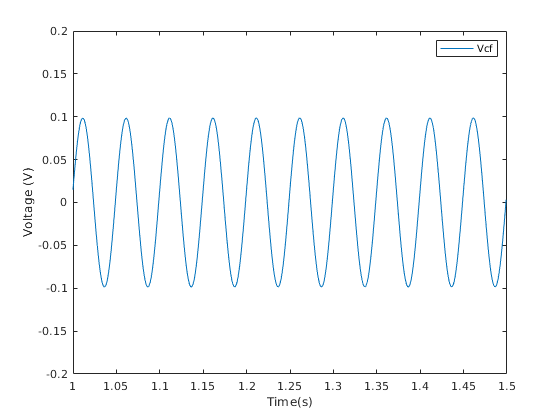

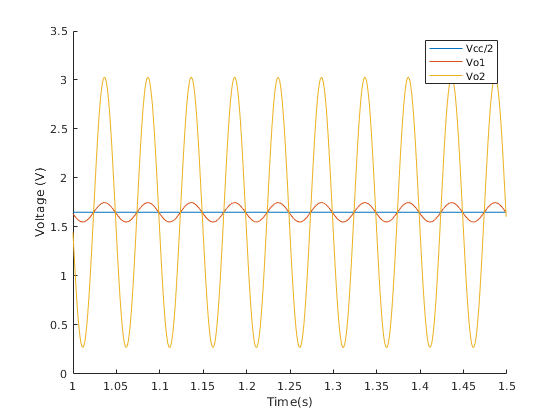

if plotting ==1
    figure
    plot(simOut.VCf.Time(start_time:end_time), simOut.VCf.Data(start_time:end_time))
    xlabel("Time(s)")
    ylabel("Voltage (V)")
    xlim([1,1.5]);
    ylim([-0.2,0.2])
    legend("Vcf");
    %figure
    %plot(i.Time(start_time:end_time), i.Data(start_time:end_time))
    figure
    hold on, plot(simOut.Vo1.Time(start_time:end_time), 1.65*ones(1,end_time-start_time+1))
    plot(simOut.Vo1.Time(start_time:end_time), simOut.Vo1.Data(start_time:end_time))
    plot(simOut.Vo2.Time(start_time:end_time), simOut.Vo2.Data(start_time:end_time)) 
    xlabel("Time(s)")
    ylabel("Voltage (V)")
    legend("Vcc/2","Vo1","Vo2");
    xlim([1,1.5])
end

magn=max(simOut.Vo2.Data(start_time:end_time))-min(simOut.Vo2.Data(start_time:end_time));

## Uncertainty propagation

% Define components of interest
load_system(model_name);
p = sdo.getParameterFromModel(model_name,{'R1','R2','R3','R4','R5','Cf'});
ps = sdo.ParameterSpace(p);
% Define their distribution
R1dist=makedist('normal','mu',p(1).Value, 'sigma',0.005*p(1).Value);
R2dist=makedist('normal','mu',p(2).Value, 'sigma',0.005*p(2).Value);
R3dist=makedist('normal','mu',p(3).Value, 'sigma',0.005*p(3).Value);
R4dist=makedist('normal','mu',p(4).Value, 'sigma',0.005*p(4).Value);
R5dist=makedist('normal','mu',p(5).Value, 'sigma',0.005*p(5).Value);
Cfdist=makedist('normal','mu',p(6).Value, 'sigma',0.005*p(6).Value);
ps = setDistribution(ps,p,[R1dist;R2dist;R3dist;R4dist;R5dist;Cfdist]);
%Gain=1e12*(1+p(5).Value/p(4).Value)/p(6).Value
rng default;   % for reproducibility
ParamValues  = sdo.sample(ps, 200); 
warning('off')
[EvalResult, Info] = uncertaintyProp_ChargeAmpl_sens(ps,ParamValues);

%figure, sdo.scatterPlot(ParamValues)

z=table2array(EvalResult);
CI=computeCI(z, 0.68); 

propUncertMC(): Recommended to use at least 3125 samples for a CI interval this large


standard_error=100*((CI(2)-CI(1))/2)/mean(z); % this is the uncertainty in percentage for 67% confidence - this is standard error
CI=computeCI(z, 0.95)

propUncertMC(): Recommended to use at least 19999 samples for a CI interval this large


CI =     2.7306    2.8138


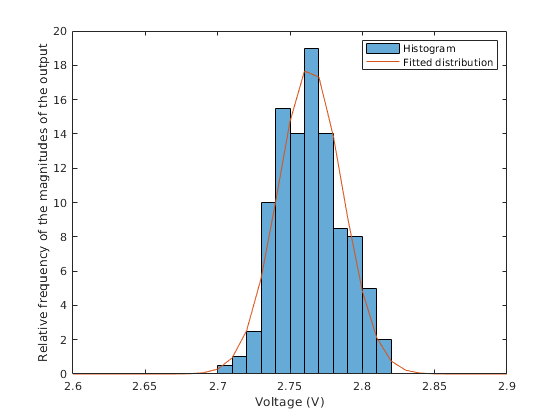


figure
histogram(z,'Normalization','pdf') %,'probability')
pd=fitdist(z,'Normal');
z1=2.6:0.01:2.9;
y=pdf(pd,z1);
hold on
plot(z1,y)
xlabel('Voltage (V)')
legend({'Histogram', 'Fitted distribution'}, 'Location','northeast');
ylabel('Relative frequency of the magnitudes of the output');
annonation_save('',"Fig4.13.jpg", SAVE_FLAG);


sensitivity = sensitivityStatistics(ParamValues,EvalResult)

sensitivity = struct with fields:
                   Correlation: [6×1 table]
               RankCorrelation: [6×1 table]
            KendallCorrelation: [6×1 table]
        StandardizedRegression: [6×1 table]
    RankStandardizedRegression: [6×1 table]
            PartialCorrelation: [6×1 table]
        RankPartialCorrelation: [6×1 table]


sensitivity.Correlation

ans = 6×1 table
          SignalProperty
          ______________

    R1        -0.11538  
    R2      -0.0077205  
    R3        0.011732  
    R4        -0.55617  
    R5         0.51513  
    Cf        -0.60927  


## Functions

function CI = computeCI(MCfuncVals, confInterval)
%This code is from the function propUncertMC by Joe Klebba, 3/2021
%Find smallest interval containing 'confInterval' of the values
sorted = sort(MCfuncVals);
range = ceil(confInterval*length(sorted));
smallestInterval = inf;
bottom=-inf; top=inf;
for idxLow = 1:length(sorted)
    idxHigh = idxLow+range;
    if idxHigh > length(sorted)
        break
    end
    low = sorted(idxLow);
    high = sorted(idxHigh);
    if (high-low)<smallestInterval
        bottom = low; top = high;
        smallestInterval = high-low;
    end
end
CI = [bottom top];
if (1-confInterval)*length(sorted) < 1000
    recomm = floor(1000/(1-confInterval));
    disp("propUncertMC(): Recommended to use at least "+recomm+" samples for a CI interval this large")
end
end


--------------------------------------------------------------------------------------------------------------

function sensitivity = sensitivityStatistics(x,y)
%SENSITIVITYSTATISTICS
%
% Compute sensitivity analysis statistics for the  model.
%
% The function returns sensitivity analysis statistics, sensitivity,
% indicating which parameters, x, have the most influence on the
% requirements, y.
%
% The input argument, x, defines the parameters.  If omitted, the
% parameters specified in the function body are used.
%
% Modify the function to change the analysis techniques.
%
% Auto-generated by SSATOOL on 29-Dec-2020 13:38:31.
%

%% Specify Analysis Variables
%
% Specify parameters and requirements.
if (nargin < 1)  ||  isempty(x)
    x = getData('x');
end

if (nargin < 2)  ||  isempty(y)
    y = getData('y');
end


%% Statistics Options
%
% Specify options for statistical analysis
opts = sdo.AnalyzeOptions;
opts.Method =  {'Correlation', 'StandardizedRegression', 'PartialCorrelation'};
opts.MethodOptions = {'Linear', 'Ranked', 'Kendall'};

%% Compute Statistics
%
% Call sdo.analyze with the parameters and requirements, to determine which
% parameters most influence the requirements.
sensitivity = sdo.analyze(x,y,opts);
end

